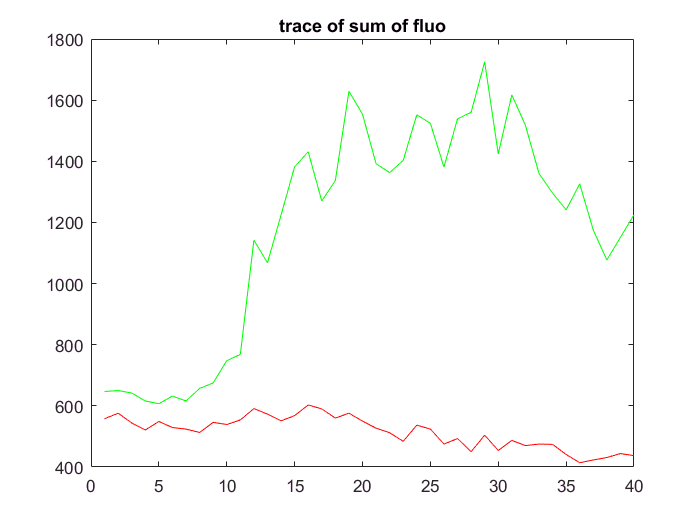

% plots actual traces
load('C:\Users\seanm\Desktop\garcia_lab_stuff\elong_search\dat\real_data\processed_data.mat');
i = 9;
data = preprocessed(i);

figure;
plot(data.greensum, 'g');
hold on
plot(data.redsum, 'r');
title('trace of sum of fluo');

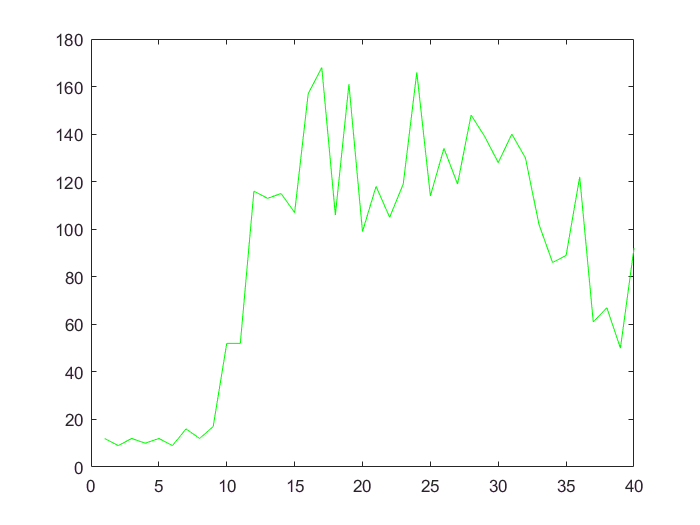


figure;
plot(data.greenmax, 'g');

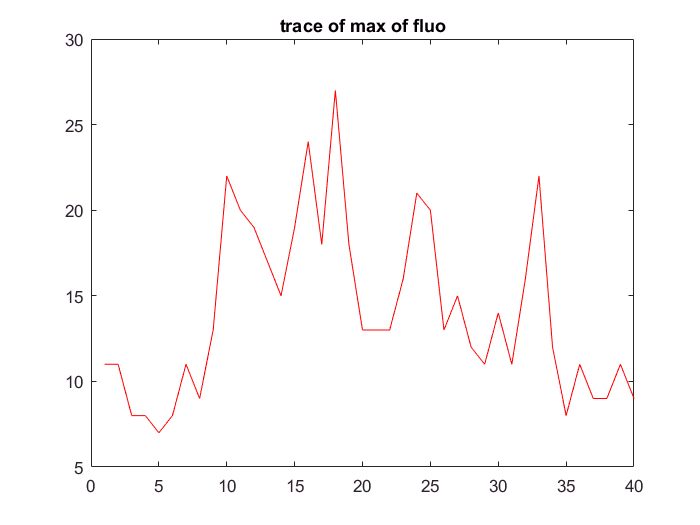

figure
plot(data.redmax, 'r');

title('trace of max of fluo');

% runs cross correlation

max_delay = 25;
project = 'real data max';
trace1 = cell([1 length(preprocessed)]);
trace2 = cell([1 length(preprocessed)]);
for i = 1:length(preprocessed)
    trace1{i} = preprocessed(i).redmax;
    trace2{i} = preprocessed(i).greenmax;
end

Undefined function or variable 'cross_corr_analysis'.

% plots synthetic data (manually add time delay)
tr = 1;
figure;
plot(data.fluo_data{1}{tr}, 'g');
hold on;
second_set = [0 data.fluo_data{2}{tr}]

second_set =    1.0e+03 *

         0    2.7070    5.5100    4.6460    0.8793    2.6095    4.4568         0         0    1.3390         0    0.8884         0    1.7003    5.2305    0.9661    1.1803    0.2680         0         0         0         0    0.0722    2.0798         0    1.0687    2.6907         0         0    1.9315    4.5981    2.5711    2.8242    3.9293    1.9715         0    0.2766    1.2438    0.4043    0.3873    1.3092    2.3437    3.4840    2.2986    1.9787    0.7436    2.5410    5.1549    0.7525    2.7815


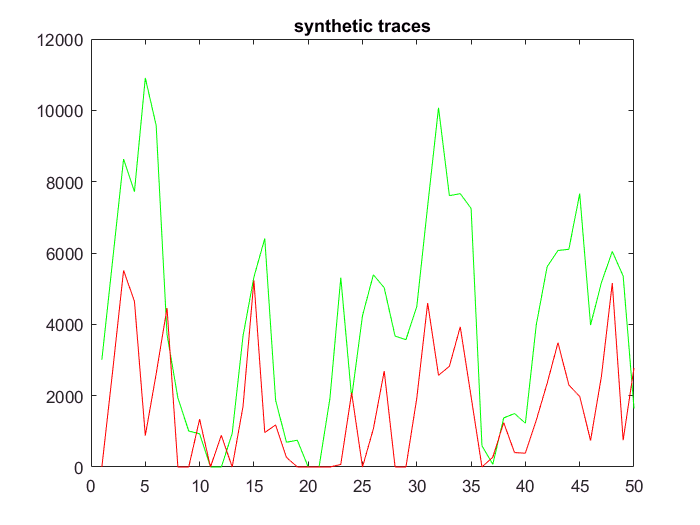

plot(second_set(1:length(second_set)-1), 'r');
title('synthetic traces');